
$$\begin{array}{l}
\mathrm{ECSE}\text{ }307-\mathrm{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\mathrm{Professor}\text{ }\mathrm{Aditya}\text{ }\mathrm{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\mathrm{TA}:\mathrm{Mohammad}\text{ }\mathrm{Afshari}\text{ }\mathrm{and}\text{ }\mathrm{Anas}\text{ }\mathrm{El}\text{ }\mathrm{Fathi}
\end{array}$$


# 
$$\begin{array}{l}
\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{Lab}\text{ }3\\
Step\text{ }Response\text{ }Identification\text{ }of\text{ }a\text{ }Dynamical\text{ }System
\end{array}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID   = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID   = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, we will identify the transfer function and the parameters of QNET Allied Motion CL40 Series Coreless DC Motor (model 16705). We will use Matlab to interact with the DC Motor in order to generate inputs/outputs data. We will then use this data to identify the model parameters of the DC motor using the properties of its time response.

## **1. Introduction**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

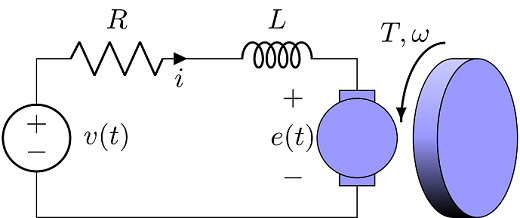

Following an input voltage $v$ we can observe the angular velocity of the shaft $\omega$. The Qnet DC Motor transfer function between the voltage and the angular velocity is usually approximated to a first order transfer function with parameters $G$ and $\tau$.


$$ \frac{\Omega(s) }{ V(s) } =  \frac{ G }{ \tau s + 1 } $$


- $G$ is the `DC gain`, also called `steady state gain`. The `DC gain` represent the amplitude ratio between the steady state step response and the step input.

- $\tau$ is is the `time constant`. The `time constant` might be regarded as the time for the system's step response to reach $1-e^{-1} \approx 63.2$ % of its final value.

For a generic first order system, the parameters $G$ and $\tau$ can be extracted from the plot of the system step response (the response of the system following a constant input):

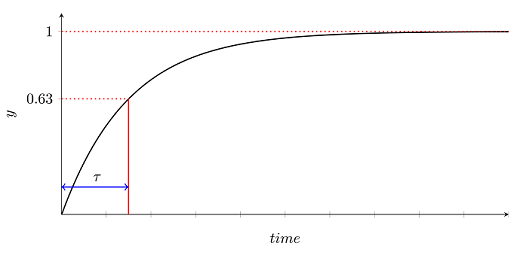

## **2. Qnet DC Motor**

## *2.1. Setting up Qnet DC Motor*

Download the `QNET DC Motor Quick Start Guide.pdf` from myCourse [Labs](https://mycourses2.mcgill.ca/d2l/le/content/305096/Home) folder. Follow carefully step 1, 2 and 4 in the guide to make sure your Qnet DC Motor is setup correctly.

## **2.2 Interfacing with Qnet DC Motor**

We provide a `MATLAB` function that interfaces with the Qnet DC Motor. Download the file `QnetDCMotor.m` and put it in the same folder as this liveScript.

There is no need to understand the implementation of `QnetDCMotor.m`, however, you can access detailed documentation of this function by doing:

doc QnetDCMotor

In order to start a new communication from `MATLAB` to the Qnet DC Motor we need to do (You might get some warnings, you can ignore them):

Motor = QnetDCMotor();

After a successful connexion, the Qnet DC Motor status led should turn from red to green. This means that motor is on. You can turn off, turn on, or reset (turn off then on) the motor by doing:

Motor.off(); % Set the power to off
Motor.on(); % Set the power to on
Motor.reset(); % Reset the power to off than on.

The input interface to send a voltage to the QnetDC Motor is the command `drive` of `QnetDCMotor`. The `drive` command takes 3 arguments:

- The voltage applied to the motor's armature in volts.

- The time when this voltage is applied in seconds.

- The duration of the drive command in seconds.

For example the follwoing code sends a 2V command after 1 second during 5 seconds

input = 2;     % volts
delay = 1;     % second
duration = 5;  % seconds
Motor.reset(); % reset the motor power
% Drive Motor with the specified voltage and duration starting from
% the specified delay.
Motor.drive(input, delay, duration)
Motor.off();  % Stop the motor

Notice the use of the `reset` before the `drive` command and `off` after the `drive` command. `reset` will also set to zero the internal DC Motor timer, so the delay used in the `drive` command is counted correctly. If nothing is done after the `drive` command, the Motor still receives the last applied voltage, hence the use of `off` to stop the Motor.

The outputs of a `Qnet DC Motor` are 4 values in a form of arrays:

- Use `Motor.time()` to retrieve the time history.

- Use `Motor.current()` to retrieve the history of the armature current in amper.

- Use `Motor.velocity()` to retrieve the history of the DC motor angular velocity in radian per second.

- Use `Motor.angle()` to retrieve the history of the DC motor angle in radian.

For example we can get the resulting angular velocity from the previous drive command and plot it by doing

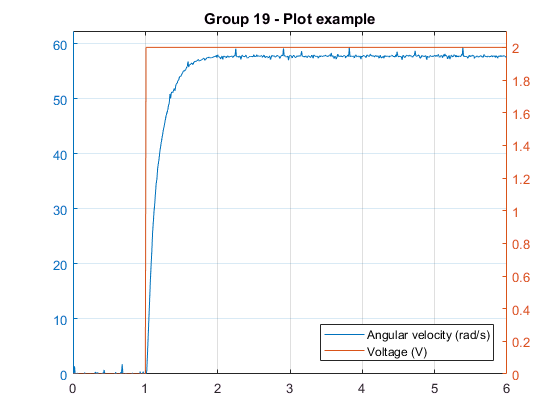

t = Motor.time();
y = Motor.velocity();
v = Motor.voltage();

figure(1)
clf;
yyaxis left
plot(t, y)
ylim([0 1.05*max(y)])
yyaxis right
plot(t, v)
ylim([0 1.05*max(v)])
xlim([0 duration+delay])
legend(['Angular velocity (' Motor.Units '/s)'], 'Voltage (V)',...
    'location', 'southeast');
title(sprintf('Group %d - Plot example', GroupeNum));
grid on

## **3. Data collection**

## *3.1. Collecting new data*

We want to generate and collect a step response of the Qnet DC Motor. For this we will send a fixed voltage signal $V_{in} = 6$ volts and measure the angular velocity $\Omega$.

However, because of static friction, the transfer function between voltage and angular velocity is non linear for small voltages. To avoid this problem, we will apply a constant reference voltage of $V_{ref} = 4$ volts, before collecting the step input response.

## *Question 1 (2 marks)*

Complete the code to send a reference voltage of 4V for 5 seconds followed by a voltage of 6V for 5 additional seconds.

Vref = 4; % Reference signal
Tref = 5; % Duration of reference signal (more than 1 second)
Vin = 6; % Input signal
Tin = 5; % Duration of input signal



Motor.reset();

% Write the drive command here
Motor.drive(Vref,0,Tref);
Motor.drive(Vin,5,Tin);
Motor.off();

## *3.2. Saving data*

Now we will save the generated data in `Question 1`. The following code retrieve the data and save it into a MAT-file Lab3Data.mat. You should submit this file with the final LiveScript and the PDF report.

t = Motor.time(Tref-1, Tref + Tin);
y = Motor.velocity(Tref-1, Tref + Tin);
v = Motor.voltage(Tref-1, Tref + Tin);

Data.y = y;
Data.t = t;
Data.v = v;
Data.Vref = Vref;
Data.Tref = Tref;
Data.Vin = Vin;
Data.Tin = Tin;

save('Lab3Data', 'Data', 'Students', 'GroupeNum');

## *3.2. Loading saved data*

From now on if your work is lost or corrupted you can just re-load your collected data instead of repeating the above experiment. Notice that if you re-run the liveScript the data will be re-generated automatically. To avoid loosing time, it is better to run section per section (Ctrl + Enter).

If you decide to load your saved data set the variable `loadSavedData` to `true`, and run the following

loadSavedData = false;
if(loadSavedData)
    load('Lab3Data');
    
    y = Data.y;
    t = Data.t;
    v = Data.v;
    Vref = Data.Vref;
    Tref = Data.Tref;
    Vin = Data.Vin;
    Tin = Data.Tin;
end

## *Question 2 (1 mark)*

Complete the following code to plot your data

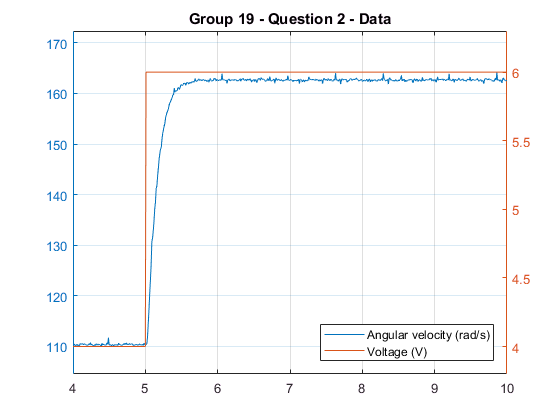

y = Data.y;
t = Data.t;
v = Data.v;

figure(2)
clf;
yyaxis left
% plot angular velocity vs time
plot(t,y);
ylim([0.95*min(y) 1.05*max(y)])
yyaxis right
% plot voltage vs time
plot(t,v);
ylim([0.95*min(v) 1.05*max(v)])
xlim([Tref-1 Tref + Tin])
legend(['Angular velocity (' Motor.Units '/s)'], 'Voltage (V)',...
    'location', 'southeast');
title(sprintf('Group %d - Question 2 - Data', GroupeNum));
grid on

## **2. System identification**

## **2.1. Data analysis**

Using the resulting plot from `Question 2` we can read values in the graph and deduce the DC gain and time constant.

You also can observe that the measurement of the angular velocity is noisy, we can overcome this problem by taking an approximate average value, instead of point by point values.

For example, we can get a better approximation of the reference angular velocity $\Omega_{ref}$ resulting from $V_{ref}$ by doing:

Yref = mean(y(t < Tref));

## *Question 3 (3 marks)*

From the plot in `Question 2` find the values of DC gain and time constant.

Gain = (166-110)/(6-4) % From the graph, we approximated the gain by calculating 

Gain = 28

                       % the difference in angular velocity over the change in voltage
                       
Ytau = 0.63*(166-110)+110 % 63% increase of its initial value 

Ytau = 145.2800


Tau = 0.1300 % Given to us in the table, it is the corresponding value to 145.2800 (Ytau)

Tau = 0.1300

## **2.2. Identification validation**

We can use `MATLAB` to validate the calculated values of the DC gain and time constant. For this we can simulate a first order system with those values and compare it to the experimental results.

## *Question 4 (1 mark)*

Define a first order transfer function with the DC gain and time constant that you have obtained

s = tf('s');
H = Gain/(Tau*s+1);

The following code simulate your transfer function with a 2 volts input. We are using `MATLAB` function `lsim` to simulate a transfer function with a defined input and time.

tSim = 0:0.01:Tin; % create a time signal
uSim = (Vin-Vref)*ones(size(tSim)); % create a constant voltage of 2 volts
uSim(1) = 0; % the first value of the voltage is zero
ySim = Yref + lsim(H, uSim, tSim); % simulate

The following code plots the simulation superposed to the experimental results

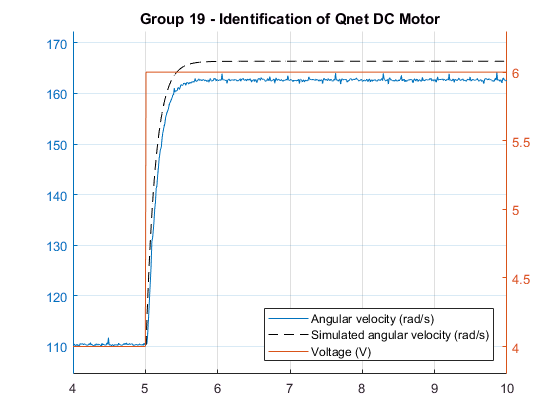

figure(3);
clf;
yyaxis left
hold on
plot(t, y)
plot(tSim + Tref, ySim, '--k')
ylim([0.95*min(y) 1.05*max(y)])
yyaxis right
plot(t, v)
ylim([0.95*min(v) 1.05*max(v)])
legend(['Angular velocity (' Motor.Units '/s)'],...
    ['Simulated angular velocity (' Motor.Units '/s)'],...
    'Voltage (V)', 'location', 'southeast');
title(sprintf('Group %d - Identification of Qnet DC Motor', GroupeNum));
grid on

We can measure the goodness of fit of the transfer function prediction by computing the Root-mean-square error (RMSE) between the experimental data and the predicted angular velocity with the model.


$$ RMSE = \sqrt{\frac{\sum_{i=1}^{n}(y_{Sim}(i) - y_{Exp}(i))^2}{n}} $$


## *Question 5 (2 marks)*

- Complete the code to compute the RMSE of your fit

yExp = y(t >= 5); % get the values of y that will be compared with ySim
RMSE = sqrt(sum((ySim-yExp).^2)/length(ySim))

RMSE = 3.8649

- Can you tweak the values of the DC gain and time constant to get a better fit of the experimental data? Complete the following code to change the values of Gain and Tau, re-define your transfer function, re-simulate the output, and re-plot the new fit.

Gain = 25.9988;
Tau = 0.15;
H = Gain/(Tau*s+1);
ySim = Yref+lsim(H, uSim, tSim);
RMSE = sqrt(sum((ySim-yExp).^2)/length(ySim))

RMSE = 0.8107

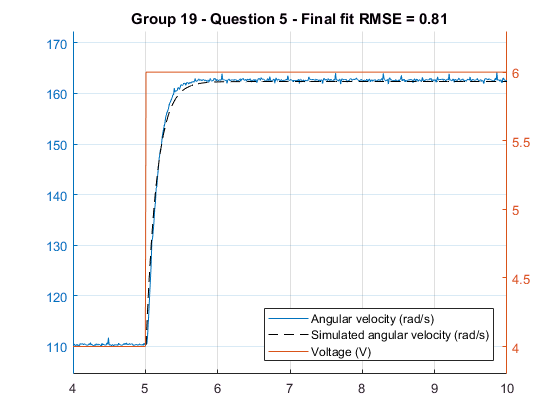


figure(4);
clf;
yyaxis left
hold on
plot(t, y)
plot(tSim + Tref, ySim, '--k')
ylim([0.95*min(y) 1.05*max(y)])
yyaxis right
plot(t, v)
ylim([0.95*min(v) 1.05*max(v)])
legend(['Angular velocity (' Motor.Units '/s)'],...
    ['Simulated angular velocity (' Motor.Units '/s)'],...
    'Voltage (V)', 'location', 'southeast');
title(sprintf('Group %d - Question 5 - Final fit RMSE = %4.2f', GroupeNum, RMSE));
grid on

## *Question 6 (1 mark)*

The experiment presented in this Lab is usually performed in DC Motors to extract the Motor viscous friction constant $b$. Knowing that the transfer function of the DC Motor can be written as:


$$ H(s) = \frac{K_t}{J R s + b R + K_t K_e} $$


Where 

Kt = 0.035; % Torque proportionality constant
Ke = 0.035; % Back electromotive proportionality constant
R = 8.4;    % Electric resistance

and J is the Motor inertia (depends on the mass connected to the shaft).

Calculate the Motor viscous friction constant $b$.

b = (Kt*(1/(Gain*R)-Ke/R)) % Solved for b from the given formula on paper

b = 1.4430e-05